## **Deep Learning Model Deployment on Embedded System**

## Analyze Network for Compression

Open the network in [Deep Network Designer](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921).

load("valTable.mat")
load("trainTable.mat")
load("testTable.mat")
% Prepare Data
allTrainData = cell2mat(trainTable{:,4});
muTrain = table2array(mean(allTrainData));
sigmaTrain = table2array(std(allTrainData));
% Get Training Data and Normalize
XTrain = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(trainTable(:,4)),'UniformOutput',false);
XTest = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(testTable(:,4)),'UniformOutput',false);
XVal = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(valTable(:,4)),'UniformOutput',false);
YTrain = categorical(string(trainTable.label));
YTest = categorical(string(testTable.label));
YVal = categorical(string(valTable.label));
% Shuffle Training Data
mask = randperm(size(XTrain,1));
XTrain = XTrain(mask,:);
YTrain = YTrain(mask,:);

load("original_net.mat")
accuracyNetOriginal = testnet(net,XTest,YTest,"accuracy")

accuracyNetOriginal = 100

% deepNetworkDesigner(net)

Get a report on how much compression pruning or projection of the network can achieve by clicking the **Analyze for Compression** button in the toolstrip.

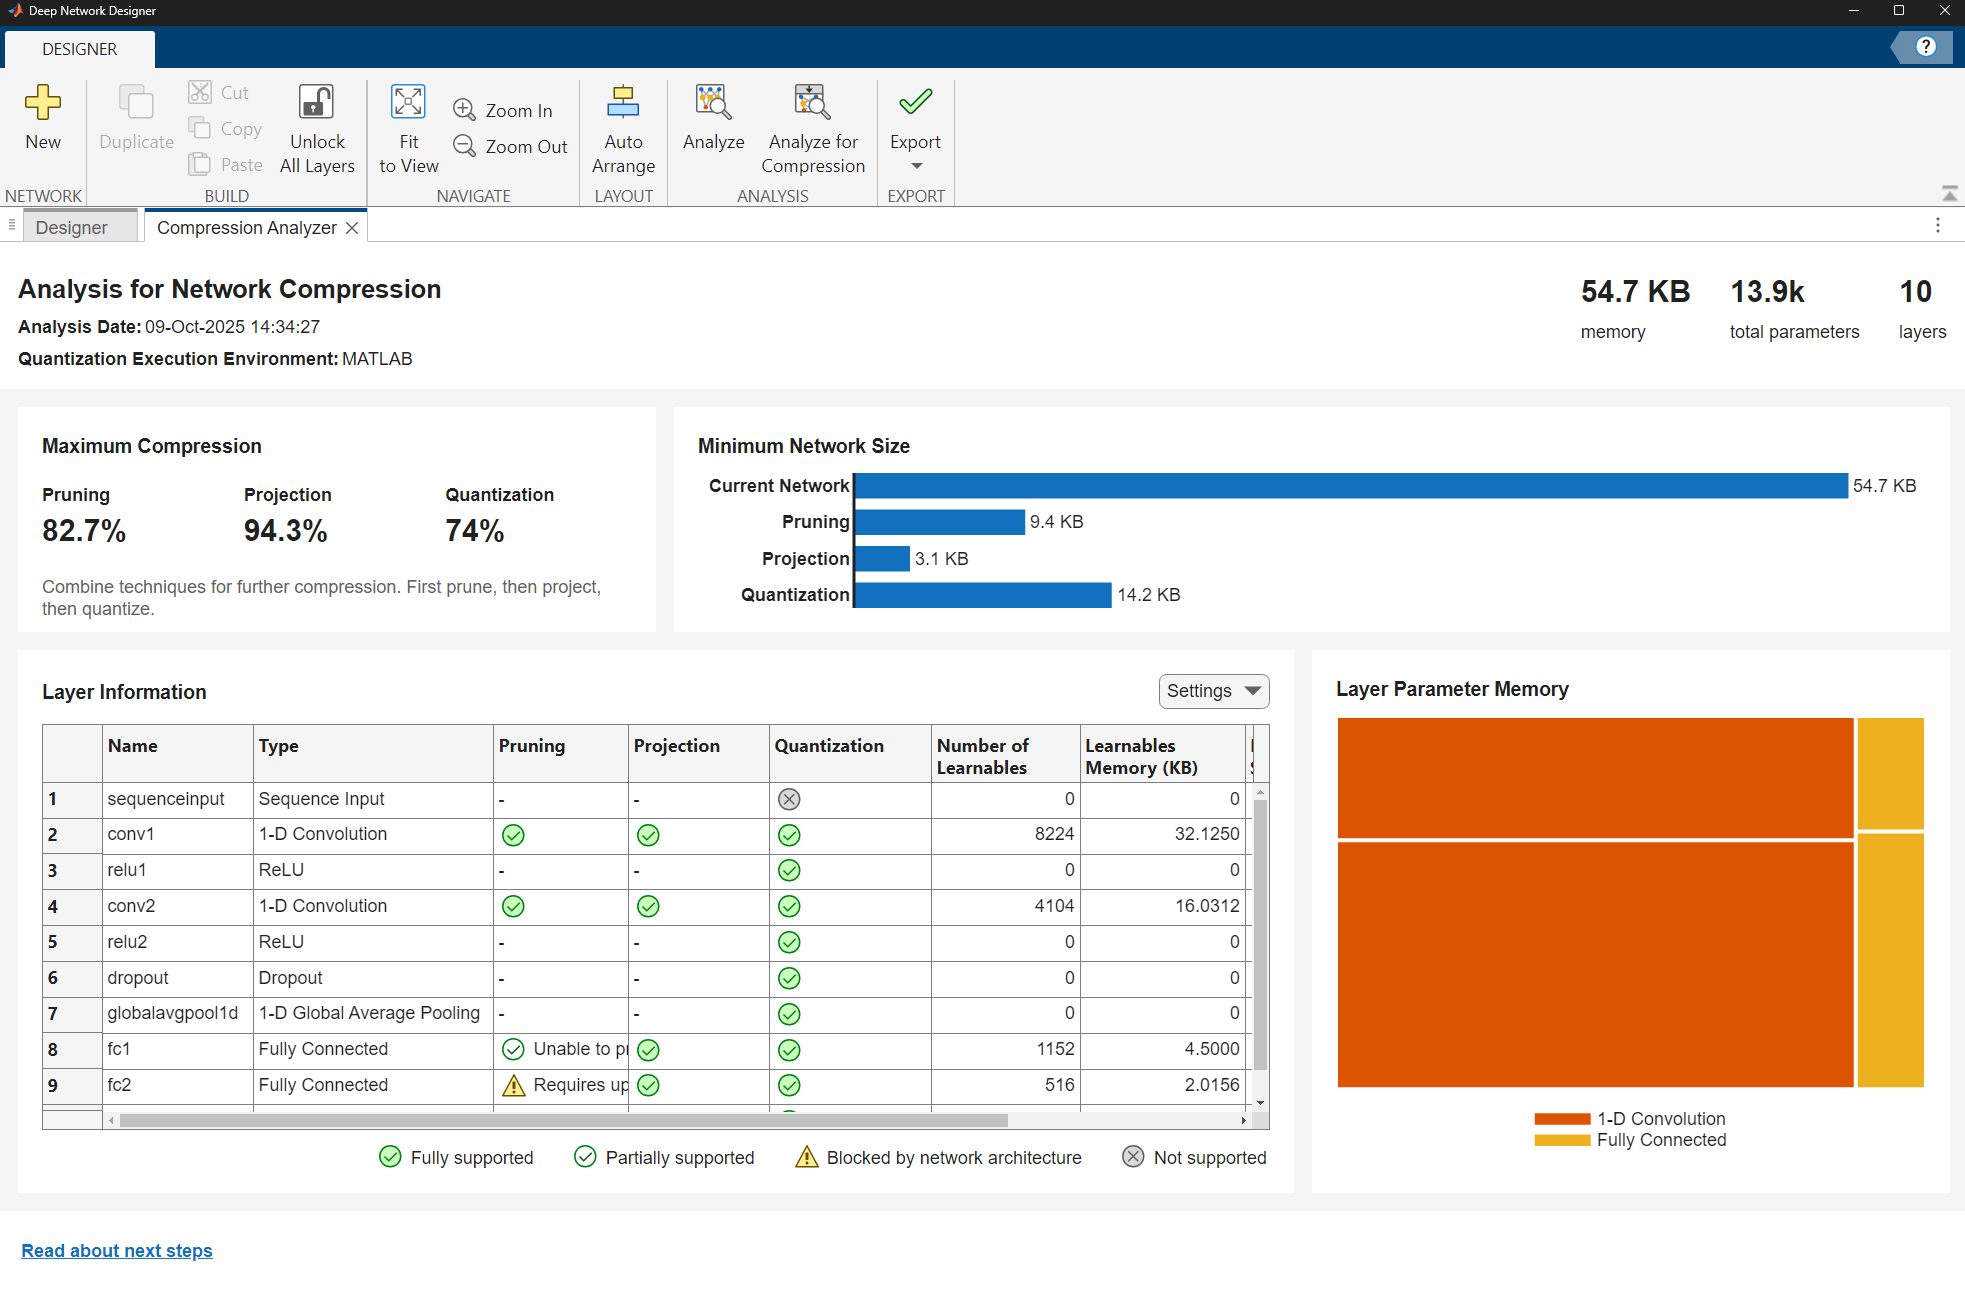

The analysis report shows that you can compress the network using either pruning, projection, or quantization. You can also use a combination of more than one technique. If you combine pruning and projection, then prune before projecting.

## Compress Network Using Pruning

To prune a convolutional network using Taylor pruning in MATLAB, iterate over the following two steps until the network size fulfills your requirements.

- Determine the importance scores of the prunable filters and remove the least important filters by applying a pruning mask.

- Retrain the network for several iterations with the updated pruning mask.

Then, use the final pruning mask to update the network architecture.

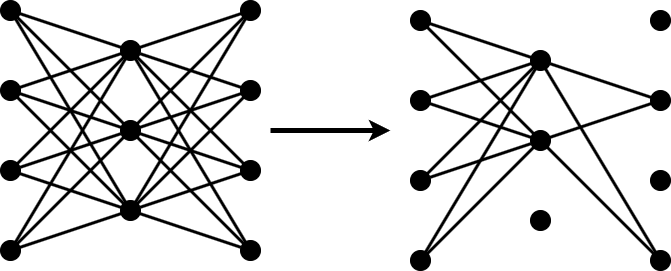**Prepare Data for Pruning**

Create a Taylor prunable network from the pretrained network using the [`taylorPrunableNetwork`](docid:nnet_ref#mw_4000fff2-10b1-4f04-8ae4-fc58dfc25946) function.

netPrunable = taylorPrunableNetwork(net);

View the number of convolution filters in the network that are suitable for pruning.

netPrunable.NumPrunables

ans = 33

Set the pruning options. Choosing the pruning options requires empirical analysis and depends on your requirements for network size and accuracy.

- `numPruningIterations` specifies the number of iterations to use for the pruning process.

- `maxToPrune` specifies the maximum number of filters to prune in each iteration of the pruning loop. In total, a maximum of `numPruningIterations * maxToPrune` filters are pruned. Note that the filters do not all contain the same number of learnable parameters.

- `numRetrainingEpochs` specifies the number of epochs to use for retraining during each iteration of the pruning loop.

- `initialLearnRate` specifies the initial learning rate used for retraining during each iteration of the pruning loop.

numPruningIterations = 3;
maxToPrune = 8;
numRetrainingEpochs = 15;
initialLearnRate = 0.01;

**Prune Pretrained Network**

Each pruning iteration consists of two steps.

First, retrain the network for `numRetrainingEpochs` epochs to fine-tune it. During the last retraining epoch, compute the importance scores of the prunable filters using the [`updateScore`](docid:nnet_ref#mw_86caa06b-acb6-4994-9ea7-9e95a002d711) function. You can do so inside the custom retraining loop because both steps require iterating over either the entire mini-batch queue or a representative subset. Both steps also require that you compute the activations and gradients of the network.

Second, update the pruning mask using the [`updatePrunables`](docid:nnet_ref#mw_d6b236c8-fb7d-403f-b90f-00ed9eacd6cc) function.

miniBatchSize = 16;
numObservations = numel(XTrain);
numIterationsPerEpoch = ceil(numObservations/miniBatchSize);

for ii = 1:numPruningIterations
    tic;
    averageGrad = [];
    averageSqGrad = [];
    fineTuningIteration = 0;    
    YTrainEncode = onehotencode(YTrain,2,'single');
    
    for jj = 1:numRetrainingEpochs
        % Shuffle indices for this epoch
        idx = randperm(numObservations);
        XTrainShuf = XTrain(idx,:);
        YTrainShuf = YTrainEncode(idx,:);

        for i = 1:numIterationsPerEpoch
            fineTuningIteration = fineTuningIteration + 1;

            % Mini-batch indices
            startIdx = (i-1)*miniBatchSize + 1;
            endIdx = min(i*miniBatchSize, numObservations);
            batchIdx = startIdx:endIdx;

            % Get batch data
            XBatch = XTrainShuf(batchIdx,:);
            YBatch = YTrainShuf(batchIdx,:);

            % Stack XBatch into a 3D array [features x 1 x batch]
            X = cat(3, XBatch{:});
            X = single(X); % ensure correct type

            % Convert YBatch to one-hot
            Y = YBatch;
            
            % Convert to dlarray if needed (depends on your model)
            X = dlarray(X, 'TCB'); % or 'CTB' etc., adjust as needed

            [~,state,gradients,pruningActivations,pruningGradients] = dlfeval(@modelLoss,netPrunable,X,Y);
            netPrunable.State = state;

            [netPrunable,averageGrad,averageSqGrad] = adamupdate(netPrunable, gradients, ...
                averageGrad,averageSqGrad, fineTuningIteration, initialLearnRate);

            if jj == numRetrainingEpochs
                netPrunable = updateScore(netPrunable,pruningActivations,pruningGradients);
            end
        end
        disp("Retraining Epoch "+jj+"/"+numRetrainingEpochs+" complete.")
    end
    netPrunable = updatePrunables(netPrunable, MaxToPrune=maxToPrune);
    t = toc;
    disp("Iteration "+ii+"/"+numPruningIterations+" complete. Elapsed time is "+t+" seconds.")
end

Retraining Epoch 1/15 complete.
Retraining Epoch 2/15 complete.
Retraining Epoch 3/15 complete.
Retraining Epoch 4/15 complete.
Retraining Epoch 5/15 complete.
Retraining Epoch 6/15 complete.
Retraining Epoch 7/15 complete.
Retraining Epoch 8/15 complete.
Retraining Epoch 9/15 complete.
Retraining Epoch 10/15 complete.
Retraining Epoch 11/15 complete.
Retraining Epoch 12/15 complete.
Retraining Epoch 13/15 complete.
Retraining Epoch 14/15 complete.
Retraining Epoch 15/15 complete.


Iteration 1/3 complete. Elapsed time is 114.72 seconds.


Retraining Epoch 1/15 complete.
Retraining Epoch 2/15 complete.
Retraining Epoch 3/15 complete.
Retraining Epoch 4/15 complete.
Retraining Epoch 5/15 complete.
Retraining Epoch 6/15 complete.
Retraining Epoch 7/15 complete.
Retraining Epoch 8/15 complete.
Retraining Epoch 9/15 complete.
Retraining Epoch 10/15 complete.
Retraining Epoch 11/15 complete.
Retraining Epoch 12/15 complete.
Retraining Epoch 13/15 complete.
Retraining Epoch 14/15 complete.
Retraining Epoch 15/15 complete.


Iteration 2/3 complete. Elapsed time is 99.7274 seconds.


Retraining Epoch 1/15 complete.
Retraining Epoch 2/15 complete.
Retraining Epoch 3/15 complete.
Retraining Epoch 4/15 complete.
Retraining Epoch 5/15 complete.
Retraining Epoch 6/15 complete.
Retraining Epoch 7/15 complete.
Retraining Epoch 8/15 complete.
Retraining Epoch 9/15 complete.
Retraining Epoch 10/15 complete.
Retraining Epoch 11/15 complete.
Retraining Epoch 12/15 complete.
Retraining Epoch 13/15 complete.
Retraining Epoch 14/15 complete.
Retraining Epoch 15/15 complete.


Iteration 3/3 complete. Elapsed time is 94.3411 seconds.


Pruning the Network

Convert the network into a `TaylorPrunableNetwork` object.

prunedNet = dlnetwork(netPrunable)

prunedNet =   dlnetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


net.Layers([2,4])

ans =   2×1 Convolution1DLayer array with layers:

     1   'conv1'   1-D Convolution   32 256×1 convolutions with stride 1 and padding 'same'
     2   'conv2'   1-D Convolution   8 16×32 convolutions with stride 1 and padding 'same'

prunedNet.Layers([2,4])

ans =   2×1 Convolution1DLayer array with layers:

     1   'conv1'   1-D Convolution   14 256×1 convolutions with stride 1 and padding 'same'
     2   'conv2'   1-D Convolution   2 16×14 convolutions with stride 1 and padding 'same'

accuracyNetPruned = testnet(prunedNet,XTest,YTest,"accuracy")

accuracyNetPruned = 36.2745

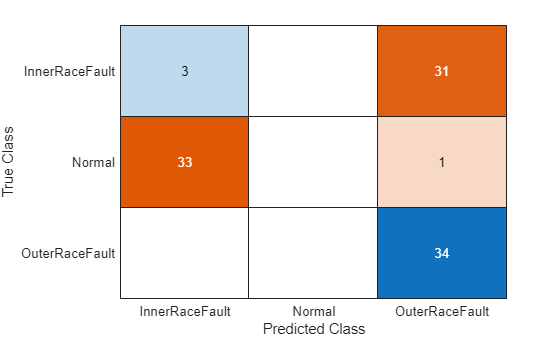

YPredPruned = scores2label(minibatchpredict(prunedNet, XTest),unique(YTrain));
figure
confusionchart(YTest,YPredPruned)

% deepNetworkDesigner(prunedNet)

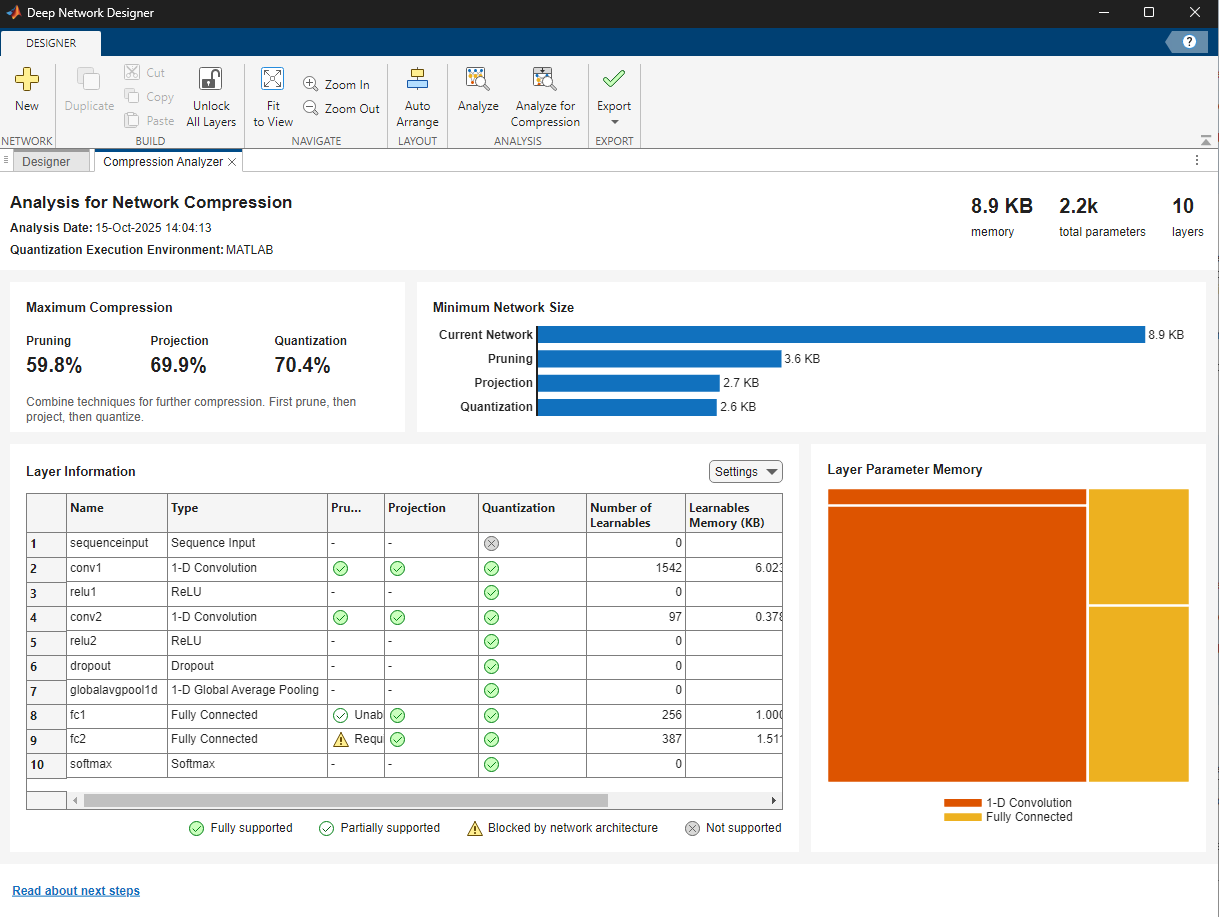

% save('pruned_net.mat','prunedNet');

**Projection**

dsX = arrayDatastore(XTrain, 'IterationDimension', 1,'OutputType','same'); % Each read: [5000 x 1]
mbqTrain = minibatchqueue(dsX, ...
    'MiniBatchSize', 256, ...
    'MiniBatchFcn', @(x) cat(3, x{:}), ...
    'MiniBatchFormat', 'TCB'); % [Time x Channel x Batch]
npca = neuronPCA(prunedNet, mbqTrain, VerbosityLevel='steps')

Using solver mode "direct".
Computing covariance matrices for activations connected to: "conv1/in","conv1/out","conv2/in","conv2/out","fc1/in","fc1/out","fc2/in","fc2/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv1/in","conv1/out","conv2/in","conv2/out","fc1/in","fc1/out","fc2/in","fc2/out"
neuronPCA analyzed 4 layers: "conv1","conv2","fc1","fc2"


npca =   neuronPCA with properties:

                  LayerNames: ["conv1"    "conv2"    "fc1"    "fc2"]
      ExplainedVarianceRange: [0 1]
    LearnablesReductionRange: [0.0220 0.8516]
            InputEigenvalues: {[1.0000]  [14×1 double]  [2×1 double]  [128×1 double]}
           InputEigenvectors: {[1]  [14×14 double]  [2×2 double]  [128×128 double]}
           OutputEigenvalues: {[14×1 double]  [2×1 double]  [128×1 double]  [3×1 double]}
          OutputEigenvectors: {[14×14 double]  [2×2 double]  [128×128 double]  [3×3 double]}


%% compress network with projection
[projectedNet, info] = compressNetworkUsingProjection(prunedNet, npca,"ExplainedVarianceGoal",0.75);

Compressed network has 53.8% fewer learnable parameters.
Projection compressed 4 layers: "conv1","conv2","fc1","fc2"


accuracyNetProj = testnet(projectedNet,XTest,YTest,"accuracy")

accuracyNetProj = 33.3333

Fine tune projected network

fineTuneOptions = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=8, ...
    MaxEpochs=20, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    ValidationData={XTrain,YTrain}, ...
    ValidationFrequency=floor(size(XTrain,1)/64), ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss");

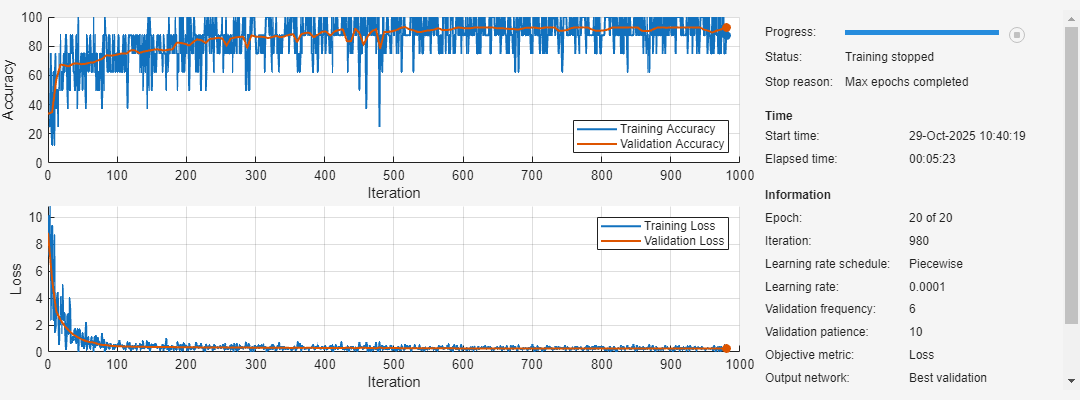

projectedNet = trainnet(XTrain,YTrain,projectedNet,"crossentropy",fineTuneOptions);

accuracyNetProjected = testnet(projectedNet,XTest,YTest,"accuracy")

accuracyNetProjected = 95.0980

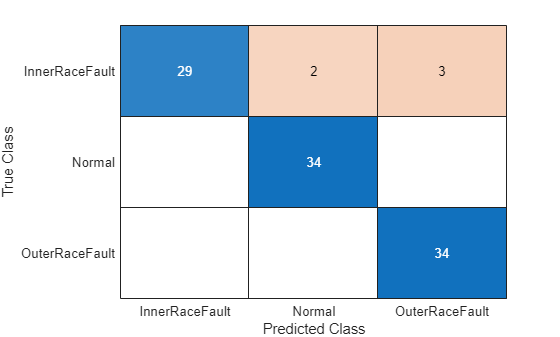

YPredProjectedFintuned = scores2label(minibatchpredict(projectedNet, XTest),unique(YTrain));
figure
confusionchart(YTest,YPredProjectedFintuned)

% deepNetworkDesigner(projectedNet)
% up_projectedNet = unpackProjectedLayers(projectedNet);

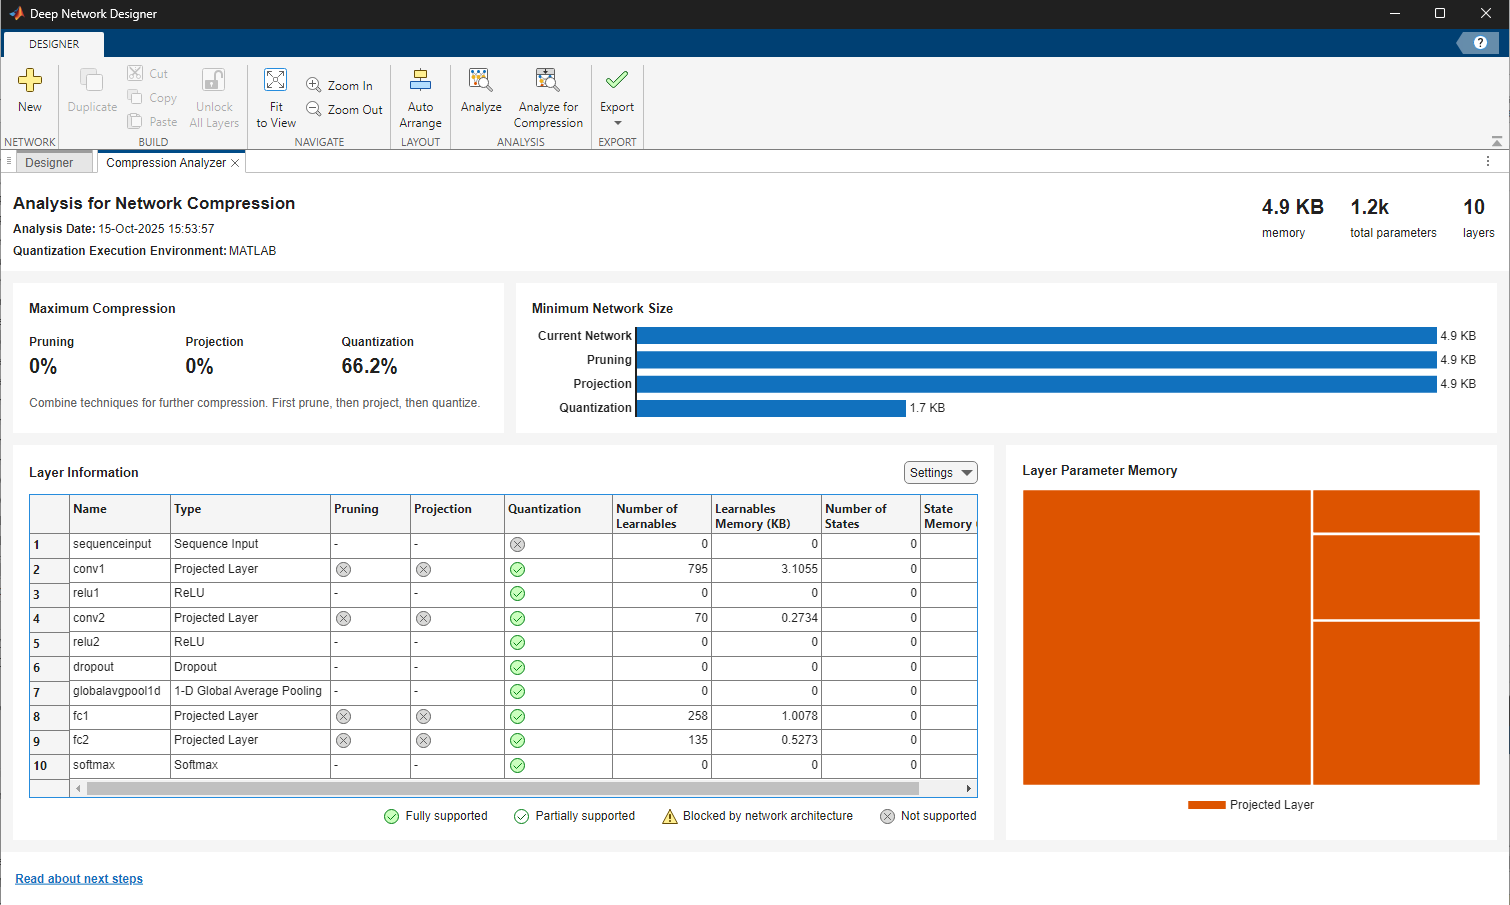

Quantize the pruned and projected netwrok

At the MATLAB command prompt, open the app.

quantObj = dlquantizer(projectedNet,ExecutionEnvironment="MATLAB");
prepareNetwork(quantObj)
dsX = arrayDatastore(XTrain, 'IterationDimension', 1,'OutputType','same'); % Each read: [5000 x 1]
dsX = gather(dsX);
calResults = calibrate(quantObj,dsX);

quantizedNet = quantize(quantObj,"ExponentScheme","Histogram");
accuracyNetQuantized = testnet(quantizedNet,XTest,YTest,"accuracy")

accuracyNetQuantized = 96.0784

qDetails = quantizationDetails(quantizedNet)

qDetails = struct with fields:
            IsQuantized: 1
          TargetLibrary: "none"
    QuantizedLayerNames: [14×1 string]
    QuantizedLearnables: [18×3 table]


% save("quantized_net.mat","quantizedNet")
deepNetworkDesigner(quantizedNet)


exportNetworkToSimulink(quantizedNet,"ModelName","quantizedNetSim","FrameBased",true);

Compare Model Compression Result    

memoryNetTrained = estimateLayerMemory(net);
memoryNetPruned = estimateLayerMemory(prunedNet);
memoryNetProjected = estimateLayerMemory(unpackProjectedLayers(projectedNet));
memoryNetQuantized = estimateLayerMemory(quantizedNet);
memory = [memoryNetTrained memoryNetPruned memoryNetProjected memoryNetQuantized];
accuracy = [accuracyNetOriginal accuracyNetPruned accuracyNetProjected accuracyNetQuantized];
figure
tiledlayout("vertical")
t1 = nexttile;
bar(t1,accuracy)
title(t1,"Accuracy")
xticklabels(["Original" "Pruned" "Projected" "Quantized"])

t2 = nexttile;
bar(t2,memory)
title(t2,"Memory (KB)")
xticklabels(["Original" "Pruned" "Projected" "Quantized"])

**Helper Function**

function [loss, state, gradients, pruningActivations, pruningGradients] = modelLoss(net,X,Y)

% Calculate network output for training.
[out, state, pruningActivations] = forward(net,X);

% Calculate loss.
loss = crossentropy(out,dlarray(Y'),'TargetCategories','independent');

% Compute pruning gradients.
gradients = dlgradient(loss,net.Learnables);
pruningGradients = dlgradient(loss,pruningActivations);
end

Calculate Memory of Supported Layers

function layerMemoryInKB = estimateLayerMemory(net)
    info = estimateNetworkMetrics(net);
    layerMemoryInMB = sum(info.("ParameterMemory (MB)"));
    layerMemoryInKB = layerMemoryInMB * 1000;
end

Count Number of Learnables and States

function numParameters = countTotalParameters(net)
    arguments
        net dlnetwork
    end
    numLearnables = cellfun(@numel,net.Learnables.Value);
    numStates = cellfun(@numel,net.State.Value);
    numParameters = sum(numLearnables) + sum(numStates);
end

Count Number of Learnables

function numLearnables = countLearnables(net)
    numLearnables = sum(cellfun(@numel,net.Learnables.Value));
end